# Chapter 6, Section 5 (Part 3)

Let's use Matlab to assist us with Example 2, page 371, in our textbook. The data is the average temperature in degrees Celsius of the earth's surface over the years 1975 through 2002.

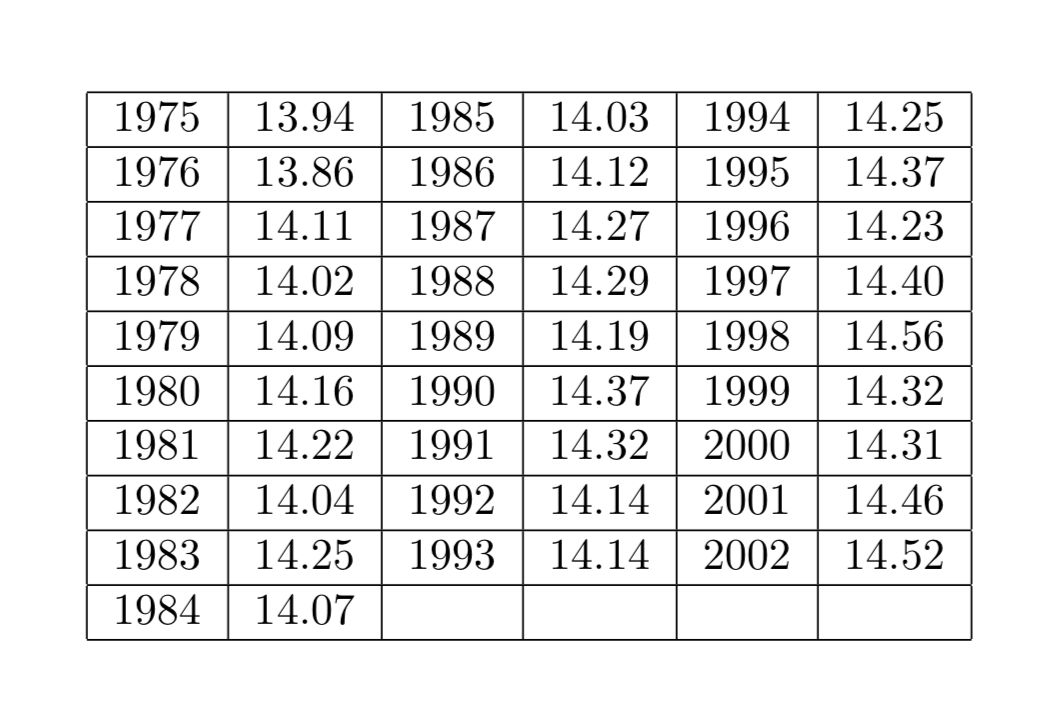

Now, we are instructed to find a line of best fit for this data. For example, our first point is $(x,y)=(1975,13.94)$, our second point is $(x,y)=(1976,13.86)$, etc., and our last point is $(x,y)=(2002,14.52)$. Let's enter these data points into the variables x and y and plot them using Matlab.

x=1975:2002;
x=x.'

x =         1975
        1976
        1977
        1978
        1979
        1980
        1981
        1982
        1983
        1984


y=[13.94 13.86 14.11 14.02 14.09 14.16 14.22 14.04 14.25 14.07...
    14.03 14.12 14.27 14.29 14.19 14.37 14.32 14.14 14.14...
    14.25 14.37 14.23 14.40 14.56 14.32 14.31 14.46 14.52];
y=y.'

y =    13.9400
   13.8600
   14.1100
   14.0200
   14.0900
   14.1600
   14.2200
   14.0400
   14.2500
   14.0700


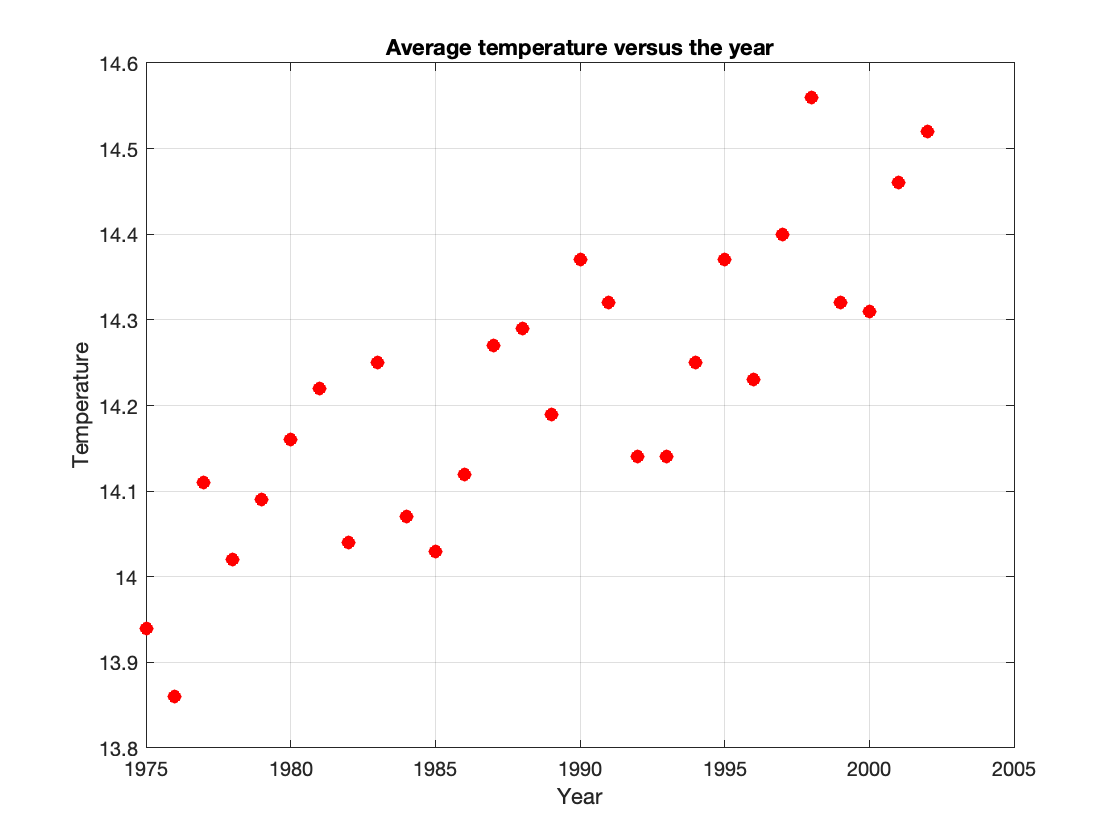

figure
plot(x,y,'ro','MarkerFaceColor','r')
xlabel('Year')
ylabel('Temperature')
title('Average temperature versus the year')
grid on

Our figure seems to say that we might be able to fit a linear model to this data. Now, if we enter these points in the equation


$$y=mx+b$$


we will get:


$$\begin{array}{rcl}
m(1975)+b&=&13.94\\
m(1976)+b&=&13.86\\
\vdots & \vdots\\
m(2002)+b&=&14.52
\end{array}$$


This can be written in vector form.


$$m\pmatrix{1975\cr 1976\cr \vdots \cr 2002}+b\pmatrix{1\cr 1\cr \vdots\cr 1}=\pmatrix{13.94\cr 13.86\cr \vdots\cr 14.52}$$


And then we can write this in matrix form.


$$\pmatrix{1975 & 1\cr 1976 & 1\cr \vdots & \vdots\cr 2002 & 1}\pmatrix{m\cr b}=\pmatrix{13.94 \cr 13.86 \cr \vdots \cr 14.52}$$


Now, we need to enter this equation $A\textbf x=\textbf b$ in Matlab. A simple way to create the matrix $A$ is to first enter both columns. Note that the first column $a_1$ of matrix $A$ is our x-values which we saved above.

a1=x

a1 =         1975
        1976
        1977
        1978
        1979
        1980
        1981
        1982
        1983
        1984


The second column $a_2$ of matrix $A$ is a column of ones the same size as the first column $a_1$.

a2=ones(size(a1))

a2 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


Now that we have our columns $a_1$ and $a_2$, we can create matrix $A$.

A=[a1,a2]

A =         1975           1
        1976           1
        1977           1
        1978           1
        1979           1
        1980           1
        1981           1
        1982           1
        1983           1
        1984           1


Note that the vector $\textbf b$ on the right side of our equation $A\textbf x=\textbf b$ is our list of $y$-values which are already stored in the variable y above.

b=y

b =    13.9400
   13.8600
   14.1100
   14.0200
   14.0900
   14.1600
   14.2200
   14.0400
   14.2500
   14.0700


Now, Matlab's command A\b will return a least squares solution.

xhat=A\b

xhat =     0.0169
  -19.3120


Now, $m$ is the first element in this answer and $b$ is the second element of this answer, so the equation of the line of best fit is:


$$\begin{array}{rcl}
y&=&mx+b\\
y&=&0.0169x-19.3120
\end{array}$$


Let's see what Matlab's **polyfit** command returns.

p=polyfit(x,y,1)

p =     0.0169  -19.3120


Same answer. Now, let's add this line to our image.

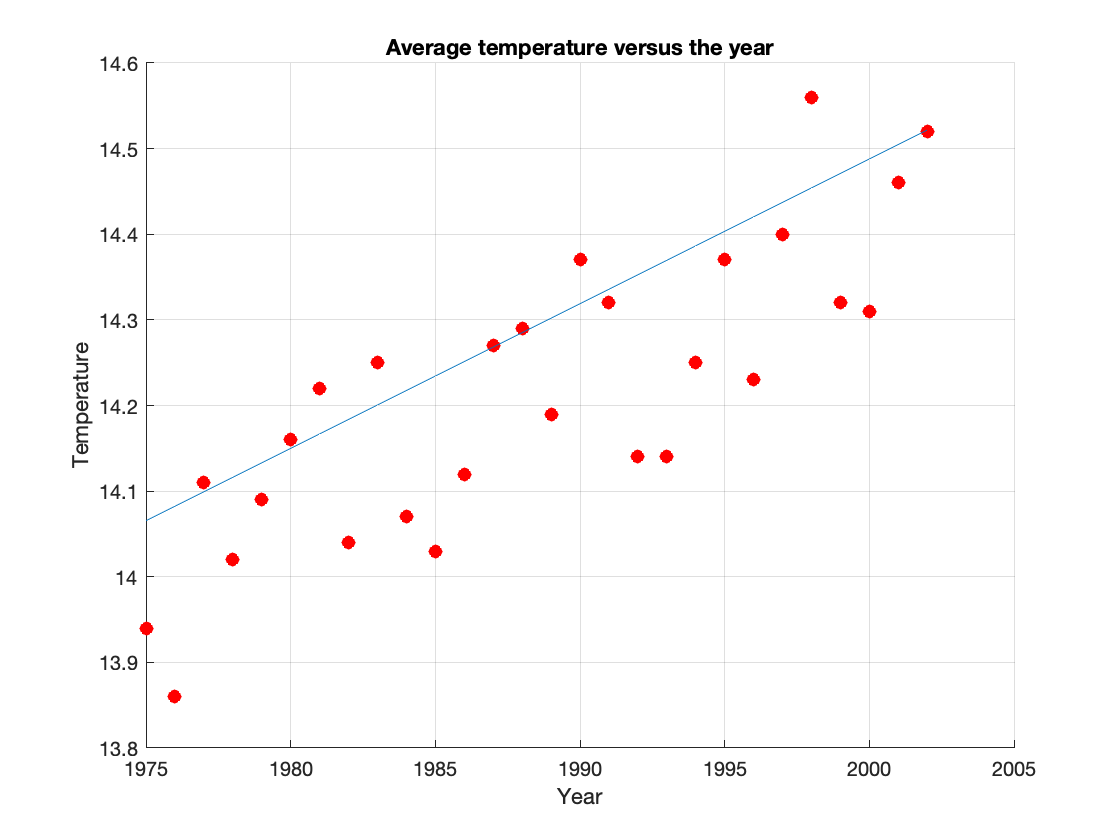

figure
hold on
plot(x,y,'ro','MarkerFaceColor','r')
u=x;
v=0.0169*x-19.3120;
plot(u,v)
xlabel('Year')
ylabel('Temperature')
title('Average temperature versus the year')
grid on

This line of best fit doesn't look correct as there are many larger errors below the line than above the line. Could it be that we didn't use enough digits from our answer? The command **format long** will display more digits and the command **format** will return Matlab to its default format.

format long
xhat

xhat =    0.016860974274768
 -19.311975916804069


format

Let's add these long format numbers to the equation of our line of best fit.


$$\begin{array}{rcl}
y&=&mx+b\\
y&=&0.016860974274768x-19.311975916804069
\end{array}$$


Now, let's add this equation to our figure.

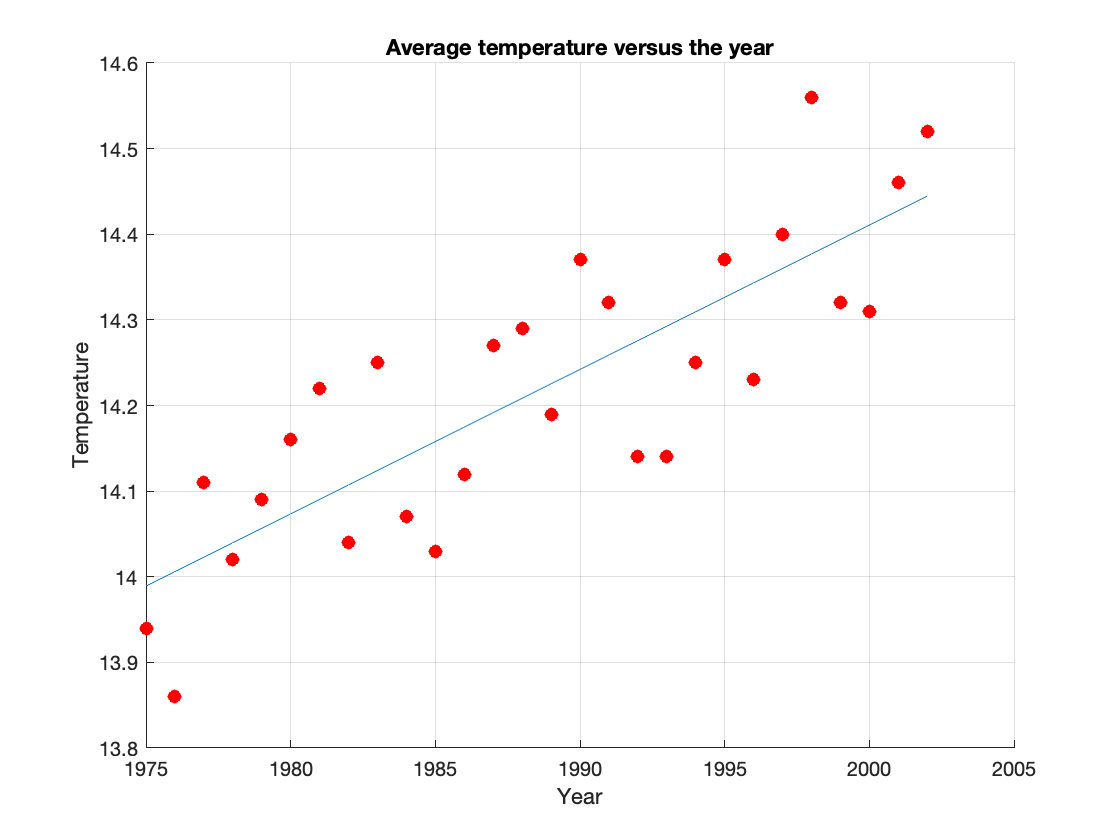

figure
hold on
plot(x,y,'ro','MarkerFaceColor','r')
u=x;
v=0.0168609742747*x-19.3111975916804069;
plot(u,v)
xlabel('Year')
ylabel('Temperature')
title('Average temperature versus the year')
grid on

Aha! Much better. Those numbers were very difficult to type in correctly. Recall that **xhat** contains our m-value and our b-value.

xhat(1)

ans = 0.0169

xhat(2)

ans = -19.3120

Even though Matlab only displays a few digits, all the digits are stored in xhat(1) and xhat(2), so we can use these to draw our line of best fit.

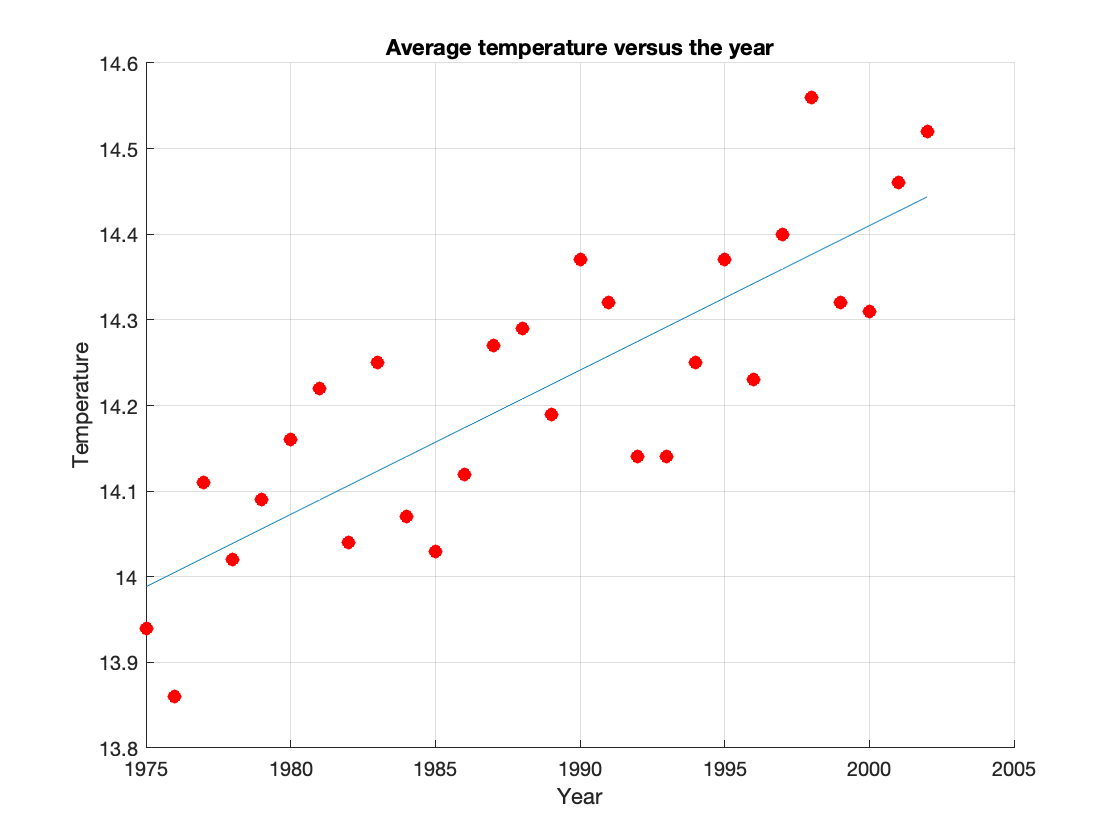

figure
hold on
plot(x,y,'ro','MarkerFaceColor','r')
u=x;
v=xhat(1)*x+xhat(2);
plot(u,v)
xlabel('Year')
ylabel('Temperature')
title('Average temperature versus the year')
grid on

Perfect! And a lot easier to type in. Now, let's use Matlab's **polyfit** and **polyval** command to draw the line of best fit.

figure
hold on
plot(x,y,'ro','MarkerFaceColor','r')
p=polyfit(x,y,1);
u=x;
v=polyval(p,x);
plot(u,v)
xlabel('Year')
ylabel('Temperature')
title('Average temperature versus the year')
grid on

Wow! Much easier. :-)